## **Challenge Problem1.1**


$$$$T = \sqrt{8m}\int_0^a\frac{dx}{\sqrt{a^4-x^4}}$$$$


m = 1;
N = 1000;
arange = linspace(0,4,N);
Tvalue = [];

% Use built-in integral function
% Use RelTol and AbsTol to manipulate singularities

for i=1:N
    a = arange(i);
    fun = @(x,a)(sqrt(8*m./(a.^4-x.^4)));
    T = integral(@(x)fun(x,a),0,a,'RelTol',0,'AbsTol',1e-5);
    Tvalue(i) = T;
end

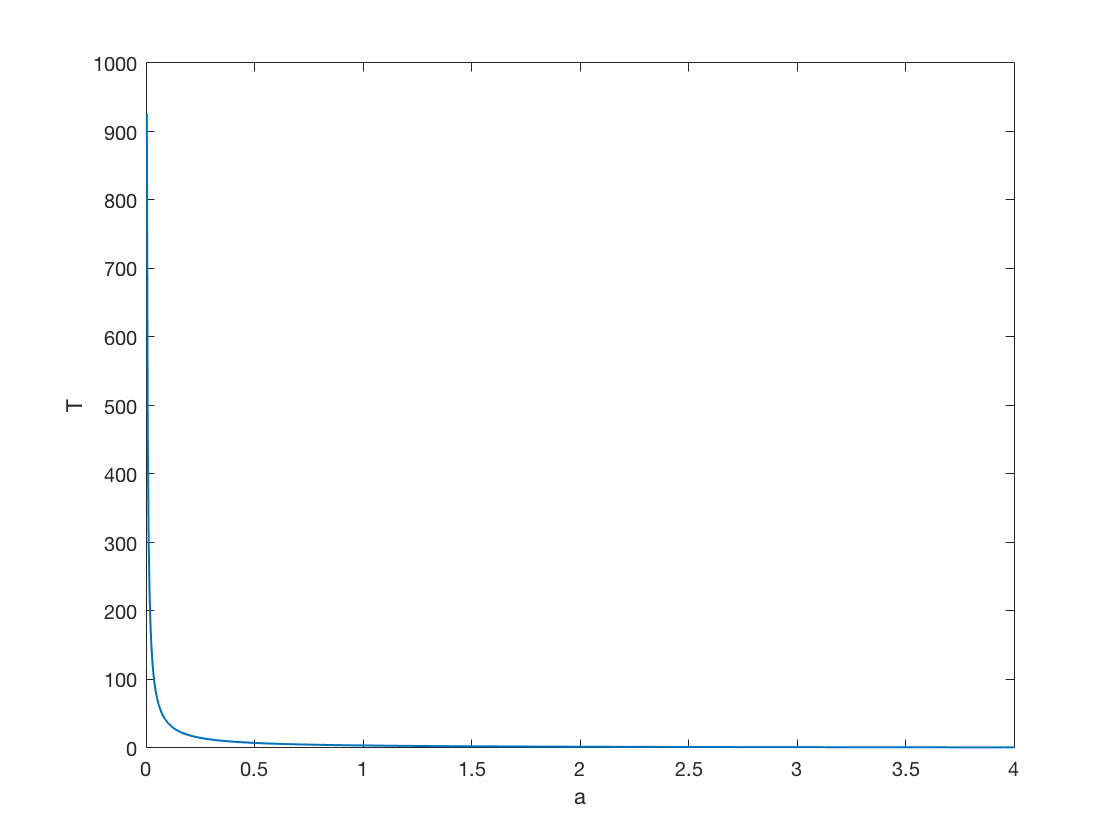


figure
plot(arange,Tvalue,'LineWidth',1)
xlabel('a')
ylabel('T')

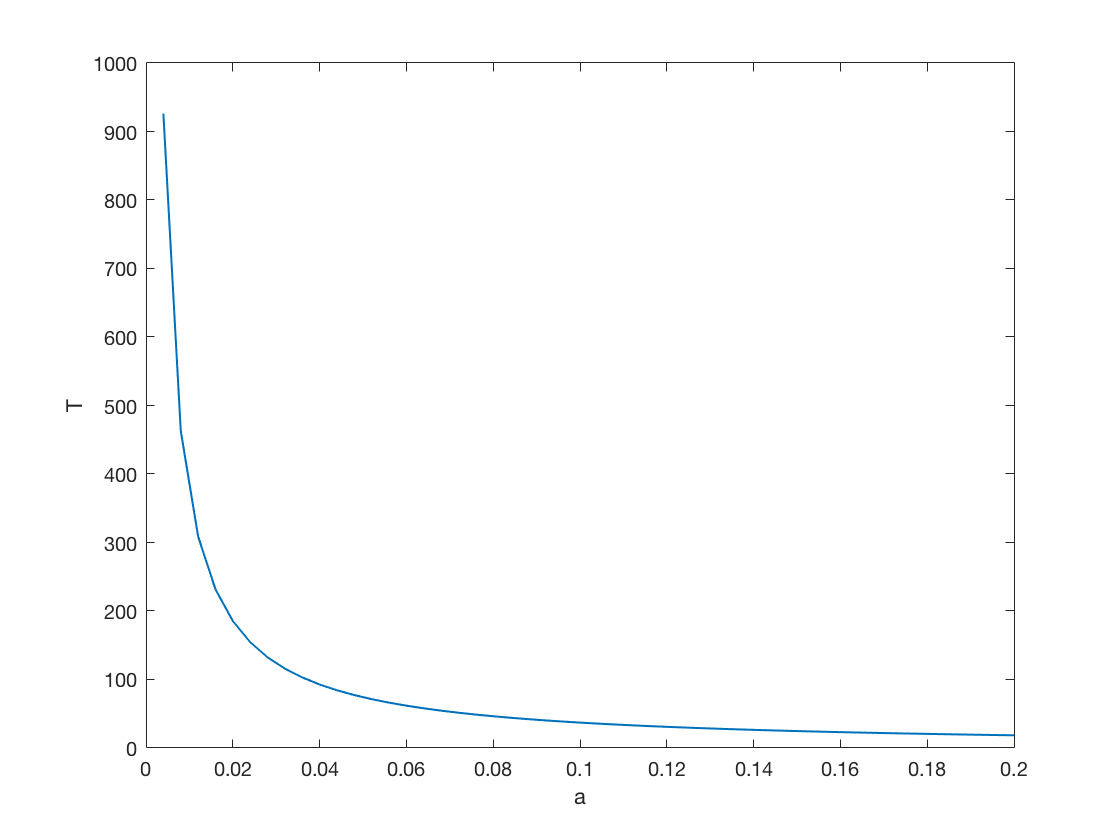


figure
plot(arange,Tvalue,'LineWidth',1)
xlabel('a')
ylabel('T')
xlim([0,0.2])